# Laboration 3

clear;
I = imread("lab3\Intro2IA_Lab3_complete\Lab3\1 Segmentation\coins.tif");
disp(size(I));
figure
imshow(I)
title("Image to be processed")
hold off

### 1.1 Watershed Segmentation

Your first task is to implement a watershed segmentation pipeline for circular objects - such as those in the coins.tif image. You will use the Distance Transform in your implementation.

Create a function segment watershed that takes a gray-scale image as input and outputs a labelling of the image, with one label (value) for each distinct object in the image. For this task, we can assume that the dark part of the image constitutes the objects, and the bright part constitutes the background. You should aim at getting a similar result to the one shown in Fig. 1

Ismall = I(1:505, 1:394);
Ismallblur = imgaussfilt(Ismall, 8);
Ibin = im2bw(Ismallblur, 0.3);
Ibin_clean = imclose(Ibin_clean, strel('disk', 3));

Idist = bwdist(Ibin_clean);
I_whed = watershed(-Idist);

marked = (uint8(~Ibin_clean)).*I_whed;

Ilabel = bwlabel(Ibin_clean, 4); 


figure
subplot(2,4,1)
imshow(Ismall)
subplot(2,4,2)
imshow(Ibin_clean)
subplot(2,4,3)
imshow(mat2gray(Idist))
subplot(2,4,4)
imshow(label2rgb(I_whed, 'jet', 'k'))
title('Watershed Result')
axis image
subplot(2,4,5)
imagesc(marked)
axis image


I = imread("lab3\Intro2IA_Lab3_complete\Lab3\1 Segmentation\coins.tif");
labels = segment_watershed(I);
plot_intensity_landscape(I);

figure;
imshow(I);
hold on;    
RGB_labels = label2rgb(labels, 'jet', 'w', 'shuffle');
h = imshow(RGB_labels);
set(h, 'AlphaData', 0.5);
hold off;

function labelling = segment_watershed(I)
    I = imgaussfilt(I, 2);
    Ibin = im2bw(I, 0.3);
    Ibin_open = imopen(Ibin, strel('disk', 3))
    Ibin_close = imclose(Ibin_open, strel('disk', 3));
    Idist = bwdist(Ibin_close);

    I_wshed = watershed(-Idist);

    labelling = (uint8(~Ibin_close)).*I_wshed;
end

function plot_intensity_landscape(I)
    [x,y]=size(I);
    X=1:double(x);
    Y=1:double(y);
    [xx,yy]=meshgrid(Y,X);
    landscape=((im2double(I)*-1)+1.);
    figure;
    subplot(1,2,1)
    mesh(xx,yy,landscape);
    axis square
    colorbar
    subplot(1,2,2)
    imshow(I)
    axis auto
end

### 1.2 Canny Edge and Hough transform

Discontinuities in the intensity function of an image correspond to the locations of edges.

Canny was proposed 1983. Consists of 3 main steps:

Gaussian gradient computation,

non-maxima suppression

hysteresis thresholding

I = imread("Intro2IA_Lab3_complete\Lab3\1 Segmentation\coins.tif");
combined = I+150;
bw = canny(I, 3, 0, 0.29);
bw2 = edge(I,"canny",0.29,3);
combined(bw2) = I(bw2);


figure
subplot(1,3,1)
imshow(bw)
title("Edge detection, implemented")
subplot(1,3,2)
imshow(bw2)
title("Edge detection, matlab")
subplot(1,3,3)
imshow(combined);
hold off

function edges = canny(I, g, T_high, T_low)
    A = imgaussfilt(I, g);
    dx_kernel = [-1, 0, 1; -2, 0, 2; -1, 0, 1];
    dy_kernel = [1, 2, 1; 0, 0, 0; -1, -2, -1];
    x_filtered = conv2(A, dx_kernel, 'same');
    y_filtered = conv2(A, dy_kernel, 'same');
    arah = atan2 (y_filtered, x_filtered);
    arah = arah*180/pi;
    
    pan=size(A,1);
    leb=size(A,2);
    %positive angles
    for i=1:pan
        for j=1:leb
            if (arah(i,j)<0) 
                arah(i,j)=360+arah(i,j);
            end
        end
    end

    arah2=zeros(pan, leb);
    %round directions to nearest 0, 45, 90, or 135
    for i = 1  : pan
        for j = 1 : leb
            if ((arah(i, j) >= 0 ) && (arah(i, j) < 22.5) || (arah(i, j) >= 157.5) && (arah(i, j) < 202.5) || (arah(i, j) >= 337.5) && (arah(i, j) <= 360))
                arah2(i, j) = 0;
            elseif ((arah(i, j) >= 22.5) && (arah(i, j) < 67.5) || (arah(i, j) >= 202.5) && (arah(i, j) < 247.5))
                arah2(i, j) = 45;
            elseif ((arah(i, j) >= 67.5 && arah(i, j) < 112.5) || (arah(i, j) >= 247.5 && arah(i, j) < 292.5))
                arah2(i, j) = 90;
            elseif ((arah(i, j) >= 112.5 && arah(i, j) < 157.5) || (arah(i, j) >= 292.5 && arah(i, j) < 337.5))
                arah2(i, j) = 135;
            end
        end
    end    
    
    magnitude = (x_filtered.^2) + (y_filtered.^2);
    magnitude2 = sqrt(magnitude);
    
    BW = zeros (pan, leb);

    %non-maximum suppression
    for i=2:pan-1
        for j=2:leb-1
            if (arah2(i,j)==0)
                BW(i,j) = (magnitude2(i,j) == max([magnitude2(i,j), magnitude2(i,j+1), magnitude2(i,j-1)]));
            elseif (arah2(i,j)==45)
                BW(i,j) = (magnitude2(i,j) == max([magnitude2(i,j), magnitude2(i+1,j-1), magnitude2(i-1,j+1)]));
            elseif (arah2(i,j)==90)
                BW(i,j) = (magnitude2(i,j) == max([magnitude2(i,j), magnitude2(i+1,j), magnitude2(i-1,j)]));
            elseif (arah2(i,j)==135)
                BW(i,j) = (magnitude2(i,j) == max([magnitude2(i,j), magnitude2(i+1,j+1), magnitude2(i-1,j-1)]));
            end
        end
    end
    
    BW = BW.*magnitude2;
    
    %Hysteresis Thresholding
    T_low = T_low * max(max(BW));
    T_high = T_high * max(max(BW));
    
    T_res = zeros (pan, leb);

    for i = 1  : pan
        for j = 1 : leb
            if (BW(i, j) < T_low)
                T_res(i, j) = 0;
            elseif (BW(i, j) > T_high)
                T_res(i, j) = 1;
            %Using 8-connected components
            elseif ( BW(i+1,j)>T_high || BW(i-1,j)>T_high || BW(i,j+1)>T_high || BW(i,j-1)>T_high || BW(i-1, j-1)>T_high || BW(i-1, j+1)>T_high || BW(i+1, j+1)>T_high || BW(i+1, j-1)>T_high)
                T_res(i,j) = 1;
            end
        end
    end

    edges = uint8(T_res.*255);

end

Find the coins in the Hough parameter space.

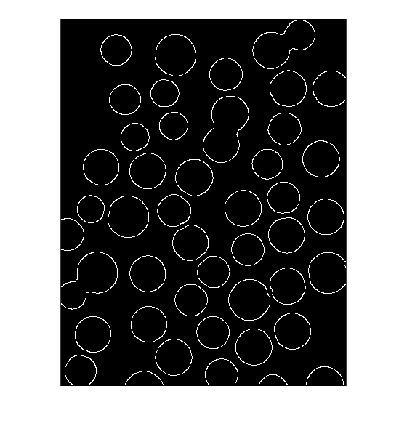

I = imread("Intro2IA_Lab3_complete\Lab3\1 Segmentation\coins.tif");

canny_out = edge(I, 'Canny', 0.29, 3);
figure
imshow(canny_out);
hold off


%x, y, radius
detected_circles = hough_trans(canny_out);

ans =    505   394    26


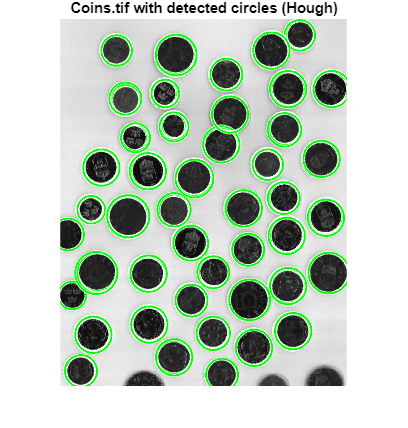

figure
imshow(I)
hold on
for i = 1:size(detected_circles, 1)
    viscircles([detected_circles(i, 2), detected_circles(i, 1)], detected_circles(i, 3), 'EdgeColor', 'g', 'LineWidth', 1.5);
end
hold off;
title("Coins.tif with detected circles (Hough)")


function out = hough_trans(edges)
    [rows, cols] = size(edges);
    min_radius = 15;
    max_radius = 40;
    radius_range = max_radius - min_radius + 1;
    
    accumulator = zeros(rows, cols, radius_range);
    theta = 0:359;  % Theta values from 0 to 359 degrees
    
    for x = 1:rows
        for y = 1:cols
            if edges(x, y)  % If the pixel is an edge (1)
                for r = min_radius:max_radius
                    for t = theta
                        a = round(x - r * cosd(t));  % Center x
                        b = round(y - r * sind(t));  % Center y
                        if (a > 0 && a <= rows && b > 0 && b <= cols)
                            accumulator(a, b, r - min_radius + 1) = accumulator(a, b, r - min_radius + 1) + 1;
                        end
                    end
                end
            end
        end
    end
    size(accumulator)
    threshold = 150;  % Threshold
    detected_circles = [];
    
    for r = min_radius:max_radius
        [centers_x, centers_y] = find(accumulator(:, :, r - min_radius + 1) > threshold);
        radii = r * ones(size(centers_x));
        detected_circles = [detected_circles; centers_x, centers_y, radii];
    end
    

    out = detected_circles;
end

### 1.3 Quantitative Evaluation

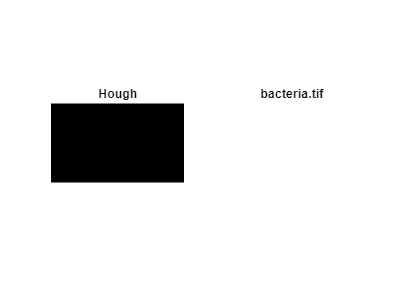

clear;
cla;

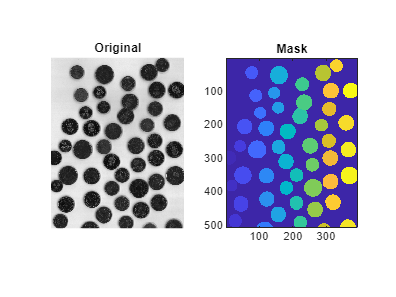

clear figure

GT = imread("Intro2IA_Lab3_complete\Lab3\1 Segmentation\coins_ground_truth.png");
I = imread("Intro2IA_Lab3_complete\Lab3\1 Segmentation\coins.tif");
watershed_res = watershed_segmentation(I, 2, 3, 3);
figure
subplot(1,2,1)
imshow(I)
title("Original")
subplot(1,2,2)
imagesc(GT)
axis image
title("Mask")

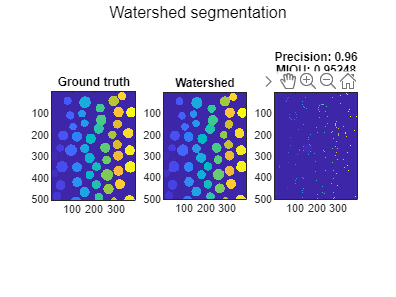


%% watershed
figure
subplot(1,3,1)
imagesc(GT)
axis image
title("Ground truth")
subplot(1,3,2)
imagesc(watershed_res)
axis image
title("Watershed")
subplot(1,3,3)
imagesc(abs(GT - watershed_res))
axis image
[miou, precision, recall] = evaluate_segmentation(watershed_res, GT);
title({['Precision: ' num2str(precision)], ...
       ['MIOU: ' num2str(miou)], ...
       ['Recall: ' num2str(recall)]}, ...
       'Interpreter', 'none');
sgtitle("Watershed segmentation")

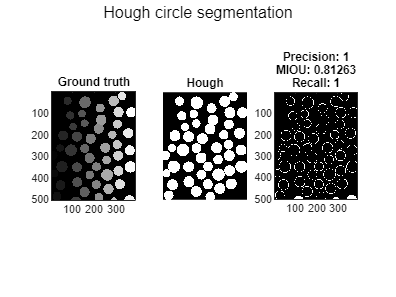


%%hough
circles = hough_circle_detection(edge(I, "canny",0.29,2), 15, 45);
centers = cat(2, circles(:,2), circles(:,1));
radiis = circles(:,3);
circles_segmented = circles2mask(centers,radiis,size(I));
circles_segmented = (uint8(circles_segmented));
GT_bw = uint8(im2bw(GT,0.001));
[miou, precision, recall] = evaluate_segmentation(circles_segmented, GT_bw, 0.5);
figure
subplot(1,3,1)
imagesc(GT)
axis image
colormap("gray")
title("Ground truth")
subplot(1,3,2)
imshow(circles_segmented*255)
title("Hough")
subplot(1,3,3)
imagesc(imabsdiff(uint8(GT_bw), circles_segmented))
axis image
title({['Precision: ' num2str(precision)], ...
       ['MIOU: ' num2str(miou)], ...
       ['Recall: ' num2str(recall)]}, ...
       'Interpreter', 'none');
sgtitle("Hough circle segmentation")

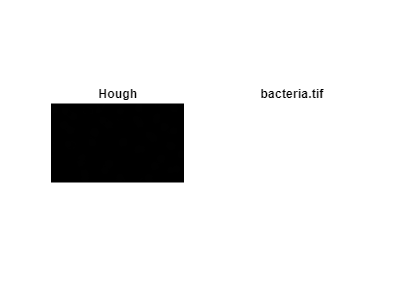


%% functions
function labelling = watershed_segmentation(I, sigma, open, close)
    I = imgaussfilt(I, sigma);

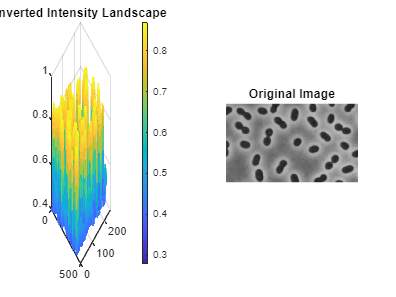

    Ibin = im2bw(I, 0.3);
    Ibin_open = imopen(Ibin, strel('disk', open));
    Ibin_close = imclose(Ibin_open, strel('disk', close));

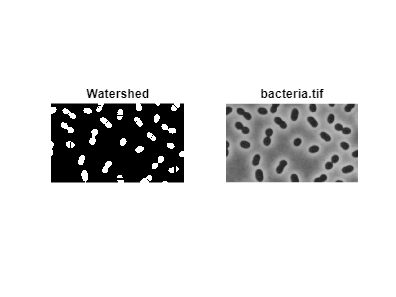

    Idist = bwdist(Ibin_close);
    I_wshed = watershed(-Idist);
    labelling = (uint8(~Ibin_close)).*I_wshed;
end

function out = hough_circle_detection(edges, min, max)
    [rows, cols] = size(edges);
    min_radius = min;
    max_radius = max;
    radius_range = max_radius - min_radius + 1;
    accumulator = zeros(rows, cols, radius_range);
    theta = 0:359;  % theta 0 to 359 degrees
    
    for x = 1:rows
        for y = 1:cols
            if edges(x, y)  % if the pixel is an edge (1)

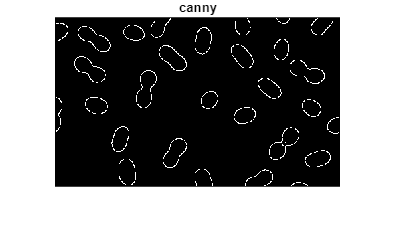

                for r = min_radius:max_radius
                    for t = theta
                        a = round(x - r * cosd(t));  %center x
                        b = round(y - r * sind(t));

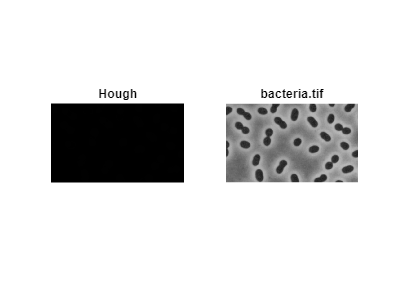

                        if (a > 0 && a <= rows && b > 0 && b <= cols)
                            accumulator(a, b, r - min_radius + 1) = accumulator(a, b, r - min_radius + 1) + 1;
                        end
                    end
                end
            end
        end
    end

    threshold = 150;  % Threshold
    detected_circles = [];
    
    for r = min_radius:max_radius
        [centers_x, centers_y] = find(accumulator(:, :, r - min_radius + 1) > threshold);
        radii = r * ones(size(centers_x));
        detected_circles = [detected_circles; centers_x, centers_y, radii];
    end
    out = detected_circles;
end

### 1.4 Generalization – Segmentation of bacteria

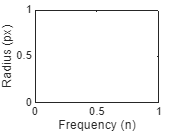

clear;
cla;

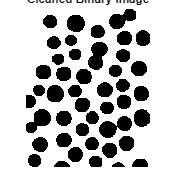

clear figure
I = imread("Intro2IA_Lab3_complete\Lab3\1 Segmentation\bacteria.tif");
intensity_landscape(I)
I_ws = watershed_segmentation(I, 2, 5, 2);
I_canny = edge(I, "canny",0.29,2);
figure
circles = hough_circle_detection(I_canny, 0, 50);
centers = cat(2, circles(:,2), circles(:,1));
radiis = circles(:,3);
circles_segmented = circles2mask(centers,radiis,size(I));
I_hough = (uint8(circles_segmented));

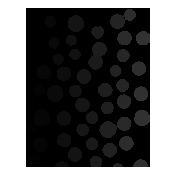


figure
subplot(1,2,1)
imshow(I_ws.*255)

title("Watershed")
subplot(1,2,2)
imshow(I)
title("bacteria.tif")


props = 50×1 struct array with fields:
    Area
    Centroid
    BoundingBox


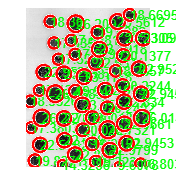

figure
imshow(I_canny)
title("canny")

figure
subplot(1,2,1)
imshow(I_hough)
title("Hough")
subplot(1,2,2)
imshow(I)
title("bacteria.tif")

function intensity_landscape(I)
    landscape = im2double(I);

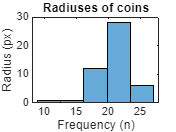

    landscape = 1 - landscape;
    [X, Y] = meshgrid(1:size(I, 2), 1:size(I, 1));
    figure;
    subplot(1, 2, 1);
    mesh(X, Y, landscape);
    axis 'auto xy';

    view(45, 30);

coins = 1×48 struct array with fields:
    index
    radius


    zlim([0.4 1])
    colorbar;
    title('Inverted Intensity Landscape');
    subplot(1, 2, 2);
    imshow(I);
    title('Original Image');
end

### 2 Image understanding

clear;

    49



cla;
clear figure;

I = imread("Intro2IA_Lab3_complete\Lab3\1 Segmentation\coins.tif");
GT = imread("Intro2IA_Lab3_complete\Lab3\1 Segmentation\coins_ground_truth.png");

Igray = imgaussfilt(I, 3); 
%binarizeing and morphological operations for clear segmentation
bin = imbinarize(Igray, 'adaptive', 'ForegroundPolarity', 'dark', 'Sensitivity', 0.5);
bin = imopen(bin, strel('disk', 1));  
bin = imclose(bin, strel('disk', 10));
figure, imshow(bin), title('Cleaned Binary Image');
% watershed did grouping very well
bin = watershed_segmentation(I,2,3,3);
figure
imshow(bin)
%extract count
[label, count] = bwlabel(bin);
%extract props for label and ignore count bc its probably wrong, do some filtering on
%the area of the props (get rid of noise)
props = regionprops(label)
props = props([props.Area] >= 30);
%done!

figure
imshow(I)
hold on
for i = 1:length(props)
    radius = (sqrt(props(i).Area / pi));
    viscircles(props(i).Centroid, radius);
    text(props(i).Centroid(1), props(i).Centroid(2), num2str((sqrt(props(i).Area / pi))), "Color",'green', FontSize=10)
    coins(i).index = i;
    coins(i).radius = round(radius);
end
hold off

figure
histogram([coins.radius], 5)
title("Radiuses of coins")
xlabel("Frequency (n)")
ylabel("Radius (px)")
coins


function labels = count_and_segment(I, sigma, open)
    I = imgaussfilt(I, sigma);
    bin = imbinarize(I, 0.29);
    bin = imerode(bin,strel('disk', open));
    Idist = bwdist(bin);
    watershed_bin = watershed(-Idist);
    labels = (uint8(~bin)).*watershed_bin;
    stats = regionprops(labels, 'Area');  % Measure size of components
    filtered = zeros(size(labels));
    for i = 1:length(stats)
        if stats(i).Area >= 30
            filtered(labels == i) = i;
        end
    end
    [labels, numberOfClusters] = bwlabel(filtered);
    numberOfClusters = numberOfClusters -1;
    disp(numberOfClusters)
end